%Sesion 4

%s = audioread("test_period_70.wav");
s = audioread("Afonso_8khz.wav");
%s = audioread("Gala_8khz.wav");
%Descomentar o comentar en función de lo esperado
[sh, B, G, AK, Tv, indv, bits] = celp_basico(s, 160, 40, 10, 0)
%[sh, B, G, AK, Tv, indv, bits] = celp_basico(s, 160, 40, 10, 1)
%[sh, B, G, AK, Tv, indv, bits] = celp_basico(s, 240, 60, 10, 0)

sh =     0.0001    0.0001   -0.0000   -0.0001   -0.0001    0.0000    0.0001    0.0000   -0.0000    0.0001    0.0001   -0.0001   -0.0001   -0.0000    0.0001    0.0002    0.0000   -0.0001   -0.0001   -0.0000    0.0001   -0.0000   -0.0001   -0.0001    0.0000    0.0001    0.0000    0.0000   -0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0001    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000


B =          0   -0.8032    0.6274    0.6985    0.3271    0.4469    0.4724    1.3398    0.7248    0.9862    0.3635    0.5563    0.7366    1.7018    0.8036    0.5841    0.6835    0.5214    1.8761    1.1078    0.3345    0.6197    1.1715    0.8628    0.5179    1.0038    0.7103    0.6704    0.6751    0.7730    0.8263   12.2485  -69.5485 -128.1911    1.7729    0.8861   -0.8541    1.2930    0.7309    0.4260    0.6642    0.5639    0.7658    0.8925    1.0885    1.2911    0.9430    0.8117    1.4818    1.2007


G =    -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0002    0.0111    0.0083    0.0116    0.0148    0.0159    0.0156    0.0133    0.0158   -0.0050   -0.0079    0.0046    0.0039    0.0046    0.0052   -0.0067    0.0095   -0.0292   -0.0138


AK =     1.0000   -0.9160    0.5942    0.0041   -0.0756   -0.2271    0.2368   -0.0405   -0.1533    0.0609   -0.1274    1.0000   -0.4845    0.0702    0.0467    0.0139   -0.0701   -0.0649   -0.0089   -0.2549   -0.0037   -0.0783    1.0000   -0.0648   -0.2421   -0.2628   -0.1285    0.1232   -0.0497   -0.2707   -0.0231   -0.0716    0.1475    1.0000   -0.0673    0.0434   -0.2685   -0.1132   -0.1618    0.0906   -0.1477   -0.1640   -0.1055    0.0273    1.0000   -0.2188   -0.1489   -0.1087   -0.0744   -0.2296


Tv =    180    66    63   137    64    93   111    60   169   107    63    73   109   120    60    63    88   161    81   150   117   171    74   130    77   113   167   143   169    83    73   130    64   164    64    65   124    66    65    67    67   136    69    68    68    66    64    64   130    63


indv =     94    80   434   352   125   139   228   318    46   354   256   257   432   175   263   264   509    46   120   369    73   496    11   318   422   439   446   330   474   408   284   450   438   434   400   275   230    34    46    23     9    54   138   241    19    26   437    11   312    61


bits = 0.6708

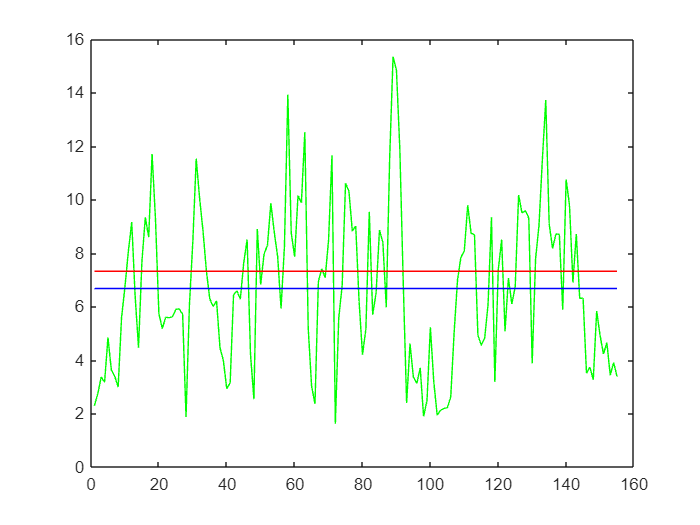

%[sh, B, G, AK, Tv, indv, bits] = celp_basico(s, 240, 60, 10, 1)

s = s';
s = s(1:size(sh,2));

SNRGlobal = SNR(s,sh);
%[SNRseg, SNRm] = SNRportramas(s, sh, 160);
[SNRseg, SNRm] = SNRportramas(s, sh, 240);

A = zeros(1, size(SNRm,2));
B = zeros(1, size(SNRm,2));

A(1,:) = SNRGlobal;
B(1,:) = SNRseg;

plot(SNRm,'g')
hold on;
plot(A,'r');
plot(B,'b');